% Set up the right toolboxes using toolboxToolbox; need to update with a
% file that is specific for our project.
% (https://github.com/ToolboxHub/ToolboxToolbox)
tbUseProject('ISETImagePipeline');

Locating project "ISETImagePipeline" within "C:\Users\William Tuten\Documents\MATLAB\projects".
  Found at "C:\Users\William Tuten\Documents\MATLAB\projects\ISETImagePipeline".
Local copy of ToolboxToolbox is up to date.
Updating "ToolboxRegistry".
Already up to date.
Obtaining "ISETImagePipeline".
fatal: destination path 'C:\Users\William Tuten\Documents\MATLAB\projects\ISETImagePipeline' already exists and is not an empty directory.
Updating "ISETPipelineToolbox".
Already up to date.
Updating "isetbio".
Already up to date.
Updating "UnitTestToolbox".
Already up to date.
Updating "RemoteDataToolbox".
Already up to date.
Updating "ExampleTestToolbox".
Already up to date.
Found "jsonlab_v1.2" and skipping update.
Updating "plotlab".
Already up to date.
Updating "ISETBioCSFGenerator".
Already up to date.
Found "Palamedes_1.8.2" and skipping update.
Updating "mQUESTPlus".
Already up to date.
Resetting path to factory state.
Adding "ToolboxToolbox" to path at "C:\Users\William Tuten\Docume


% Simulation parameters
nPixels = 64;
fieldSizeMinutes = 30;
fieldSizeDegs = fieldSizeMinutes/60;
fieldSizeDegs2 = fieldSizeDegs^2;

subjectID = 1;

% Make a cone mosaic at our test eccentricity.
eccX = 2.0; % In degs
eccY = 0.0; % In degs

% Irrelevant for now
propL = 0.55;
propS = 0.06;
propM = 1-propL-propS;
LMratio = propL/propM;


% Method from aliasing demo provided by Linqi; not clear how to set the cone ratio, so
%trying another approach for now.
theConeMosaic = ConeResponseCmosaic(eccX,eccY, 'fovealDegree', fieldSizeDegs, ...
    'pupilSize', 3, 'coneDensities', [propL propM propS 0]);

Override, will not create mosaic and optics object 
min cone aperture diameter = 3.562447 microns


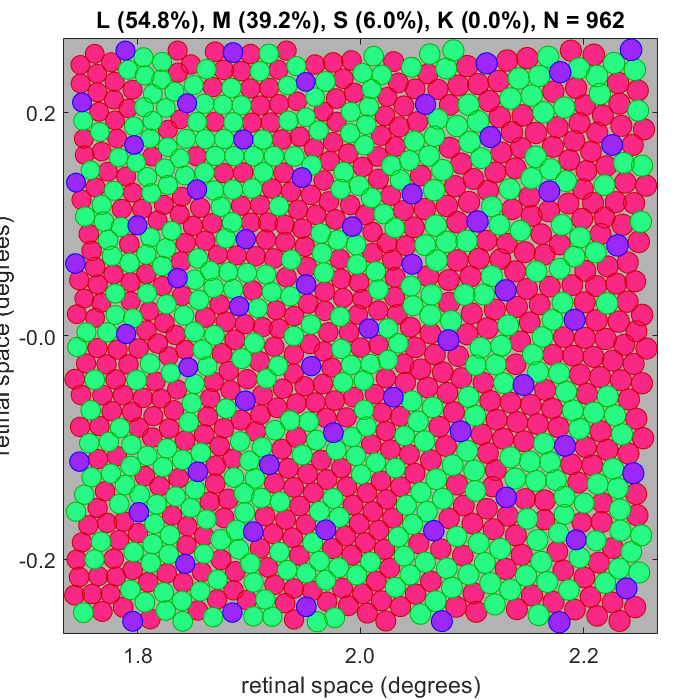

theConeMosaic.visualizeMosaic();

% Make a cone mosaic using another routine, which allows specification L M
% and S densities but is not compatible with some of the compute routines
% that foolow.
% theConeMosaic = cMosaic('eccentricityDegs', [eccX eccY], 'sizeDegs', [fieldSizeDegs fieldSizeDegs], 'coneDensities', [propL propM propS 0]);
% theConeMosaic.visualize();

## Make the optics and stimulus scene, cut and paste from the scene generation code provided by DHB.

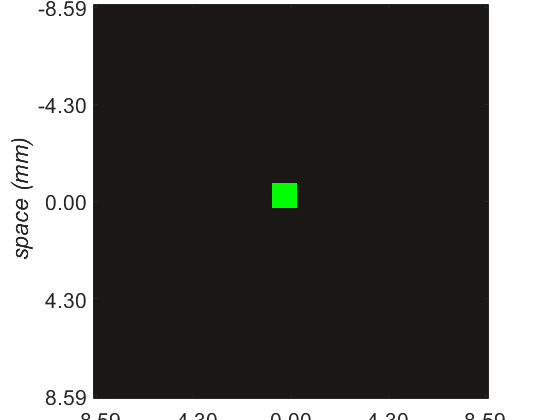

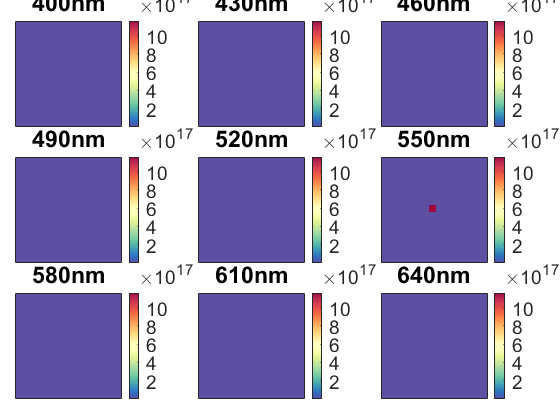

%% Set parameters 
defocusDiopters = 0.05;
pupilDiameterMm = 7;
pupilAreaMm2 = pi*(pupilDiameterMm/2)^2;
 
% Rectangle horizontal and vertical size in arcminutes. (WST updated)
spotHeightMinutes = 2;
spotWidthMinutes= 2;

% Position of rectangle. These numbers give the center position in arcmin.
%    Vertical - positive is up 
%    Horizontal - positive is right
spotVerticalPositionMinutes = 0;
spotHorizontalPositionMinutes = 0;

% Other stimulus parameters
%
% Define basic parameters of the AO stimulus
wls = (400:10:750)';
S = WlsToS(wls);

% For now, let's keep our conditions monochromatic rather than trying to
% model what we actually did, which was to make yellow with a mixture of
% our red (680 nm) and green (543 nm) primaries
spotWavelengthNm = 550; 
spotFWHMNm = 5;

% Stimulus luminance, according to Ally, was around 2844 cd/m2. The
% following lines try to work from that number back out to a sensible
% corneal irradiance, in uW, for 580 nm light
spotLuminanceCdM2 = 2844;
% spotLuminanceCdM2 = 52; % Turning down the contrast here to see how that impacts the reconstruction

% Create a relative spectrum where the only nonzero value is at the spot
% wavelength
relativeSpectrumSpot = zeros(size(wls));
wlInd = find(wls==spotWavelengthNm);
relativeSpectrumSpot(wlInd) = 1;  

% Go from lumninance to radiance. Radiance comes back using PTB convention
% of power per wlband, not power per nm.
[spotRadianceWattsM2SrWlband, spotRadianceS] = LumToRadiance(relativeSpectrumSpot, S, spotLuminanceCdM2, 'Photopic');

% And then go from radiance back out to corneal irradiance given our
% field size
cornealIrradianceWattsM2Spot = RadianceAndDegrees2ToCornIrradiance(spotRadianceWattsM2SrWlband, fieldSizeDegs2);

% Pass the result at 580 nm in uW to the scene generation code below
Mm2ToM2 = 1e-6;
WToUW = 1e6;
spotIrradianceUWM2Spot = cornealIrradianceWattsM2Spot(wlInd) * WToUW;
spotPowerUW = spotIrradianceUWM2Spot*pupilAreaMm2*Mm2ToM2;

% Let's convert spotPower to nW/deg^2, about which DHB has some intutition.
% That is, we use about 70 nW/deg^2 in the Penn AOSLO for full power
% visible stimulus at 545 nM or so.  The number here comes out ballbark
% reasonable.
UWToNW = 1000;
spotPowerNwDeg2 = spotPowerUW*UWToNW/fieldSizeDegs2;

% The underlying routine starts with a background and works in contrast.
% To deal with this, we specify a background down from desired power by
% some large factor and then take contrast as this factor.  This produces a
% spot with desired power and a background of essentially 0.  We'll patch
% that up later - doing it this way interfaces to the extant routine and is
% a kluge, but one I think we can live with.
bgFactor = 5000;
spotBgPowerUW = spotPowerUW/bgFactor;

% Convert our parameters to those that matter to the two spot routine.
% Using stimAngle of 90 means we only see spot 2, which is drawn second and
% thus always over spot 1.
stimAngle = 90;

% This is center-to-center separation of the two spots. So with values of
% zero they overlap. Because the separation is accomplished by applying
% half of it to each underlying spot, we multiply by two to convert
% position offsets to separations.  The minus sign makes the sign
% convention as described above.
spotVerticalSepMinutes = -2*spotVerticalPositionMinutes;
spotHorizontalSepMinutes = -2*spotHorizontalPositionMinutes;

% Set up two spot params
rectParams = struct(...
    'type', 'basic', ...                            % type
    'viewingDistanceMeters', 2, ...                 % viewing distance: in meters
    'wls', 400:10:750, ...                          % wavelength support of the primary SPDs: in nanometers
    'stimAngle', stimAngle, ...                     % stimulus angle in incr/decr plane
    'spotWl', spotWavelengthNm, ...                 % spot wavelength: in nm
    'spotFWHM', spotFWHMNm, ...                     % spot full width at half max: in nm
    'spotWidthDegs', spotWidthMinutes/60, ...       % spot width: in degrees
    'spotHeightDegs', spotHeightMinutes/60, ...     % spot height: in degrees
    'spotVerticalSepDegs', spotVerticalSepMinutes/60 , ... % spot center to center vertical separation: in degrees
    'spotHorizontalSepDegs', spotHorizontalSepMinutes/60, ... % spot center to center horizontal separation: in degrees
    'spotBgDegs', fieldSizeDegs, ...                % spot background: in degrees
    'spotBgPowerUW', spotBgPowerUW, ...             % spot background power: in uW
    'imagingWl', 750, ...                           % imaging beam wavelength: in nm
    'imagingFWHM', 20, ...                          % imaging beam full width at half max: in nm
    'imagingBgPowerUW', 0, ...                      % imaging beam power entering eye: in uW
    'fovDegs', fieldSizeDegs, ...                   % spatial: full scene field of view, in degrees
    'pixelsNum', nPixels, ...                       % spatial: desired size of stimulus in pixels
    'temporalModulation', 'flashed', ...            % temporal modulation mode: choose between {'flashed'}
    'temporalModulationParams', struct(...          % temporal: modulation params struct
      'stimOnFrameIndices', [1], ...                %   params relevant to the temporalModulationMode
      'stimDurationFramesNum', 1), ...              %   params relevant to the temporalModulationMode
    'frameDurationSeconds', 3/16, ...               % temporal: frame duration, in seconds
    'pupilDiameterMm', pupilDiameterMm ...          % pupil diameter mm
    );
                     
% Create a static two-spot AO scene with a particular incr-decr direction,
% and other relevant parameters. This uses compute function handle for
% two-spot AO stimuli, as commented above the parameters have been cooked
% to make one rectangular spot on a dark background.
rectComputeFunction = @sceAOTwoSpot;

% Instantiate a sceneEngine with the above sceneComputeFunctionHandle
% and the custom params.
rectSceneEngine = sceneEngine(rectComputeFunction, rectParams);

% Create a scene sequence at a particular contrast.  Here there is just one
% frame in the returned cell array of scenes. We pull out that first entry.
spotContrast = bgFactor*1.0;
rectSceneSequence = rectSceneEngine.compute(spotContrast);
rectScene = rectSceneSequence{1};

% Adjust the background.  First we'll zero out the very
% small numbers we put in to be able to specify spot power in the form of a
% contrast.
sceneRadiancePhotonsM2SrSecNm = sceneGet(rectScene,'photons');
maxPhotons = max(sceneRadiancePhotonsM2SrSecNm(:));
sceneRadiancePhotonsM2SrSecNm(sceneRadiancePhotonsM2SrSecNm(:) < 4*maxPhotons/bgFactor) = 0;

% Now approximate the background, which is effectively metameric to equal
% energy white and has a luminance of 26 cd/m2
bgLuminanceCdM2 = 26;

% Relative spectrum reflects equal energy at all wavelengths (not true, but ok for now)
relativeSpectrumBg = ones(size(wls)); 
bgRadianceWattsM2SrSecWlband = LumToRadiance(relativeSpectrumBg, S, bgLuminanceCdM2, 'Photopic');

% Convert to photonsM2SrSecNm, which are the units that ISETBio expects
bgRadiancePhotonsM2SrSecWlband = EnergyToQuanta(wls,bgRadianceWattsM2SrSecWlband);
bgRadiancePhotonsM2SrSecNm = bgRadiancePhotonsM2SrSecWlband/S(2);

% Add background to spot image
for ww = 1:length(wls)
    sceneRadiancePhotonsM2SrSecNm(:,:,ww) = ...
        sceneRadiancePhotonsM2SrSecNm(:,:,ww) + bgRadiancePhotonsM2SrSecNm(ww);
end

% Push adjusted image back into the scene. Note that default ISETBio scene
% is not represented at full double precision.  Setting bit depth to 64
% uses double precision which is what we want here.
rectScene = sceneSet(rectScene, 'bit depth', 64);
rectScene = sceneSet(rectScene,'photons',sceneRadiancePhotonsM2SrSecNm);
sceneRadianceCheck = sceneGet(rectScene,'photons');
if (max(abs(sceneRadianceCheck(:) - sceneRadiancePhotonsM2SrSecNm(:)))/mean(sceneRadiancePhotonsM2SrSecNm(:)) > 1e-10)
    error('Failure in scene set');
end

% Visualize.
%
% Use the Analyze:Line (luminance):/Horizontal menu item to select a line
% and see plot of luminance profile through the center.  Both spot and bg
% luminace come out as specified (remember that spot luminance is the sum
% of bg and specified spot luminances).
%
% Use the Plot:Radiance (photons) menu to select and ROI and plot mean
% spectrum in that region. Selecting background shows an equal energy
% spectrum, while selecting spot shows monochromatic spot on a relatively
% weak equal energy background. Not that an equal energy spectrum is not an
% equal quantal spectrum, though. You can verify equal energy by using the
% option that shows (energy) rather than photons.
% ieAddObject(rectScene);
% sceneWindow;
pause(2);
visualizeScene(rectScene)

## Working with diffraction limited optics here following code I was working from in 2020

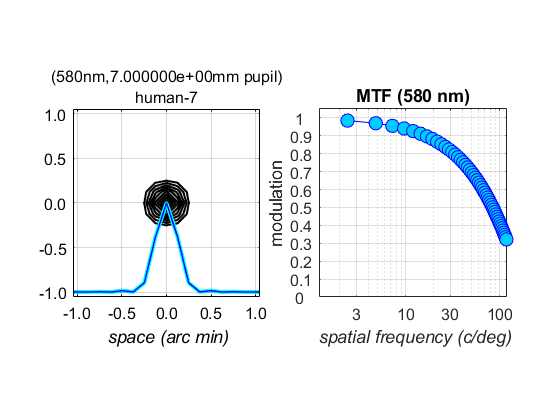

%Create the diffraction-limited optical image with no LCA
accommodatedWavelength = 580; % Pin best focus here

zCoeffs = zeros(66,1); % Simulating diffraction-limited performance here (add flag later to compare to ordinary aberrations)

% Create wvfP object
wvfP = wvfCreate('calc wavelengths', wls, 'zcoeffs', zCoeffs, ...
    'name', sprintf('human-%d', pupilDiameterMm));
wvfP = wvfSet(wvfP, 'measured pupil size', pupilDiameterMm);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMm);
% Deal with best focus by specifying that the wavefront parameters
% were measured at the wavelength we want to say is in focus. This
% is a little bit of a hack but seems OK for the diffraction limited case
% we're using here.
wvfP = wvfSet(wvfP, 'measured wavelength', accommodatedWavelength);
% Compute pupil function using 'no lca' key/value pair to turn off LCA.
% You can turn it back on (i.e. to "false") to compare the effect.
wvfPNoLca = wvfComputePupilFunction(wvfP,false,'no lca',true); % First "false" is for "showBar"?
wvfPNoLca = wvfComputePSF(wvfPNoLca); % Update wvfPNoLCA object with PSF
theOI = wvf2oi(wvfPNoLca); % Covert to wvfP to OI
opticsNoLca = oiGet(theOI, 'optics'); % Pull in the optics
opticsNoLca = opticsSet(opticsNoLca, 'model', 'shift invariant'); % Update the optics model
opticsNoLca = opticsSet(opticsNoLca, 'name', 'human-wvf-nolca'); % Rename for clarity
theOI = oiSet(theOI,'optics',opticsNoLca, 'wAngular', fieldSizeDegs); % Update the OI

% Visualize OI
visualizedSpatialSupportArcMin = 2; % Size of displayed PSF, in arc min
visualizedSpatialSfrequencyCPD = 120; % Max spatial frequency for MTF
% Visualize the PSF/OTF at the shortest wavelength (diffraction-limited)
visualizeOptics(theOI, 580, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);

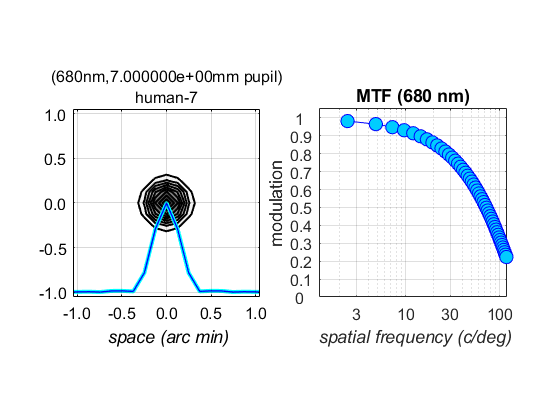

% Visualize the PSF/OTF at the longest wavelength (also diffraction-limited, but MTF
% should be a little worse "because physics")
visualizeOptics(theOI, 680, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);

## Compute the retinal image and visualize the cone response

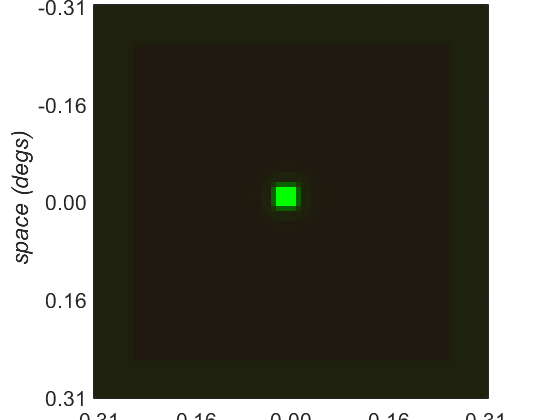

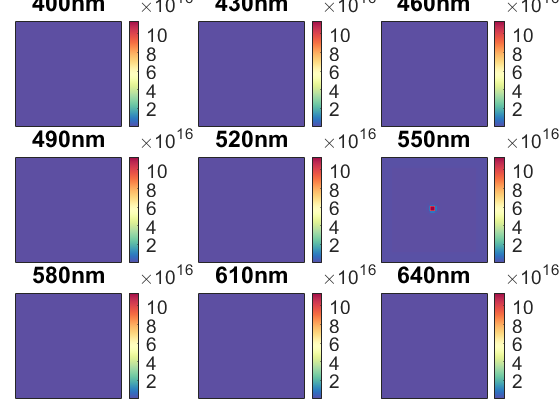

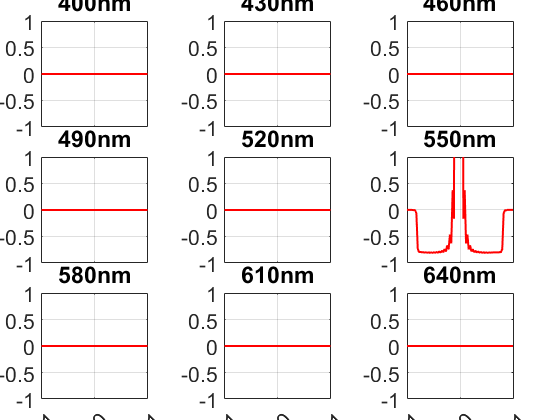

theOI = oiCompute(theOI, rectScene);

% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

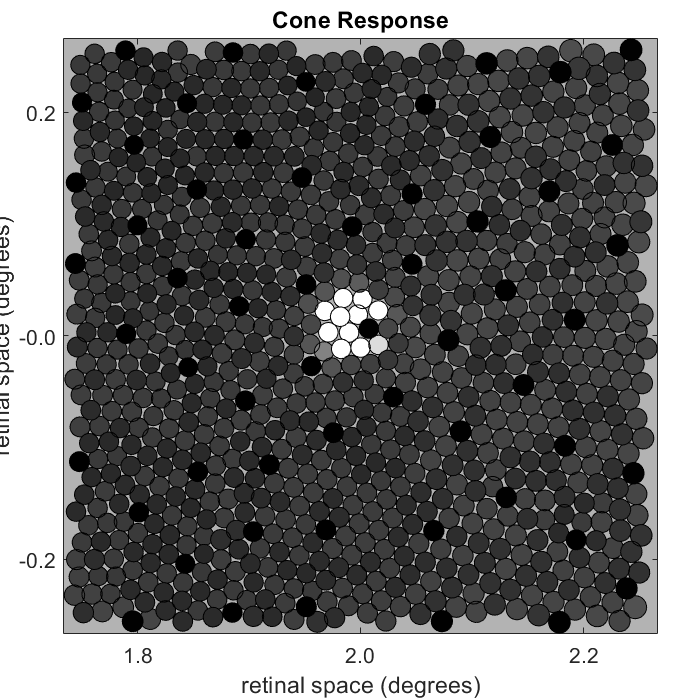

theConeMosaic.PSF = ConeResponse.psfDiffLmt(pupilDiameterMm);

coneExcitations = theConeMosaic.computeWithScene(rectScene);
% coneExcitations = theConeMosaic.compute(theOI);
% Visualize cone mosaic and its cone excitation responses
% theConeMosaic.plot('excitations', coneExcitations);
% visualizeOpticalImage(theConeMosaic.lastOI, 'displayRadianceMaps', true, ...
%                 'displayRetinalContrastProfiles', true);

% Visualize pattern of cone excitation
theConeMosaic.visualizeExcitation();